# 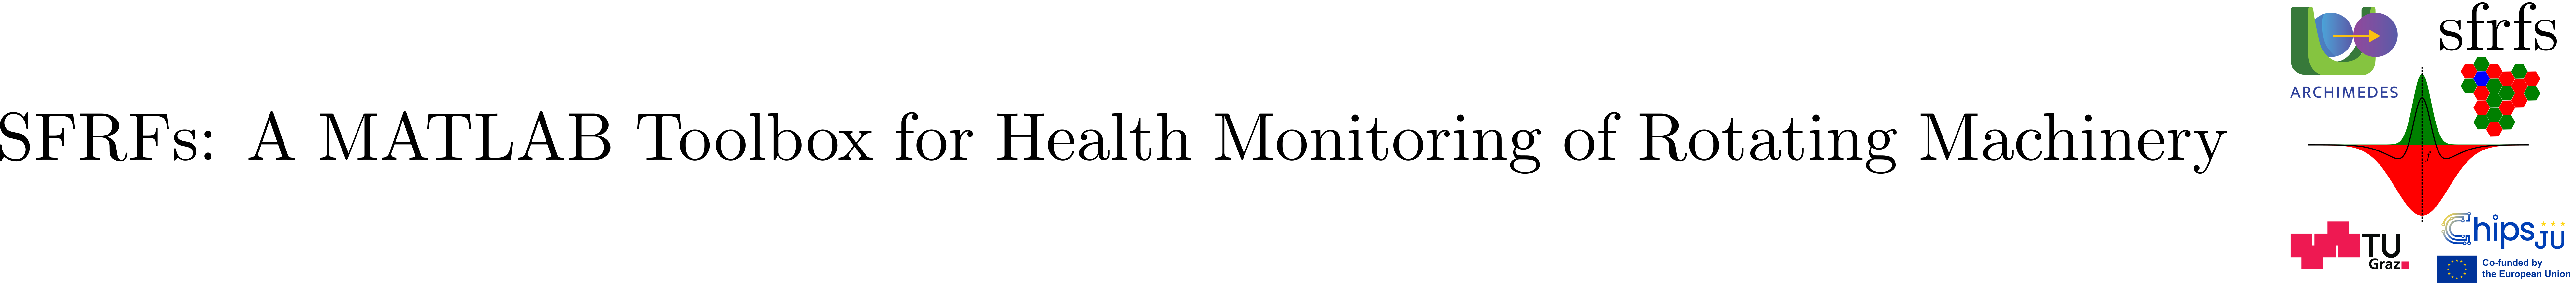

# getXJTUSYEnsemble

## Summary

Creates a `fileEnsembleDatastcreating or referencing aore` handle for an already-generated XJTU-SY ensemble. This function does not perform any data transformation; instead, it configures a datastore that references existing `.mat` ensemble member files that were created with the function createXJTUSYEnsemble and exposes their variables in a form compatible with MATLAB’s Predictive Maintenance Toolbox.

Key Features:

- References ensemble member `.mat` files without reprocessing the dataset.

- Configures the independent variables: `Label` and `SnapshotIndex`.

- Configures the condition variables: `Speed`, `Load`, and `Lifetime`.

- Configures the data variables: `HorizontalAcceleration` and `VerticalAcceleration`.

- Uses custom read and write functions that operate on the `ensembleMemberTable` stored in each file.

- Ensures the selected folder is valid and allows folder selection through a GUI if no path is provided.

Inputs:

- `outputFolder` (optional) – Path to the folder containing the ensemble’s `.mat` member files. If omitted, a folder selection dialog appears.

Output:

- `ensemble` – A fully configured `fileEnsembleDatastore` handle referencing the existing ensemble.

## Description

The function `getXJTUSYEnsemble` constructs a `fileEnsembleDatastore` handle that references existing ensemble member `.mat` files. An internal configuration assigns variable groups for independent variables, condition variables, and data variables. Independent variables identify each snapshot, condition variables describe the operating state (speed, load, lifetime), and data variables contain the measured vibration signals.

## Example

We assumed the ensemble exists and was created using the function [create`XJTUSYEnsemble`](matlab:open('./createXJTUSYEnsemble.mlx')).

% Obtain a handle to an existing ensemble by selecting its folder via GUI.
% This creates a configured fileEnsembleDatastore without loading any data.
ensemble = data.getXJTUSYEnsemble();

% Inspect the first ensemble member to inspect structure and variables
firstMember = read(ensemble);
head(firstMember)

       Label        SnapshotIndex    HorizontalAcceleration    VerticalAcceleration    Speed    Load    Lifetime
    ____________    _____________    ______________________    ____________________    _____    ____    ________

    "Bearing1_1"          1             {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"          2             {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"          3             {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"          4             {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"          5             {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"          6             {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"          7             {32768×1 double}         {32768×1 double}       35     

## API documentation

### MATLAB help

help data.getXJTUSYEnsemble

 GETXJTUSYENSEMBLE Reference a fileEnsembleDatastore from member .mat 
  files.
 
    ensemble = GETXJTUSYENSEMBLE() prompts the user to select a folder.
    ensemble = GETXJTUSYENSEMBLE(outputFolder) uses the specified folder.
 
    Input (optional):
      outputFolder - String or character vector specifying the path to the
                     folder containing the ensemble member .mat files.
                     If omitted or empty, a GUI dialog opens for selection.
 
    Output:
      ensemble     - A fileEnsembleDatastore object configured with the
                     appropriate variable names and read/write functions.
 
    Example:
      % Load an existing ensemble from a folder selected via GUI
      ensemble = getXJTUSYEnsemble();
      tbl = readall(ensemble);
      head(tbl)
 
    See also: createXJTUSYEnsemble, fileEnsembleDatastore



### MATLAB documentation

doc data.getXJTUSYEnsemble

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

Unlike the class-based entities, this helper is a standalone function, designed for the single task of obtaining the handle of an already created [`fileEnsembleDatastore`](https://www.mathworks.com/help/predmaint/ref/fileensembledatastore.html)`.`  The implementation can be found in [data.getXJTUSYEnsemble](matlab:open('../../+data/getXJTUSYEnsemble.m')).

## Test

Unit testing for the class is implemented in [testGetXJTUSYEnsemble](matlab:open('../../../tests/testGetXJTUSYEnsemble.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/testGetXJTUSYEnsemble');

Running testGetXJTUSYEnsemble
....
Done testGetXJTUSYEnsemble
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
testGetXJTUSYEnsemble/testReturnsDatastore                                       | Passed
testGetXJTUSYEnsemble/testVariablesAreConfigured                                 | Passed
testGetXJTUSYEnsemble/testReadAllMatchesOriginal                                 | Passed
testGetXJTUSYEnsemble/testErrorOnMissingFolder                                   | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).